From today's workshop, we know how to load preprocessed data from the MRI using the Freesurfer pipeline.

Further, we know how to do some basic analysis of the volumetric data, based on the grey matter we used as an example.

For today's challenge, I want you to try using the subcortical data to compare PD patients at de novo, and those that were medicated for about a year (avg.: 18 months).

Here are some information about the demographics you are dealing with: 

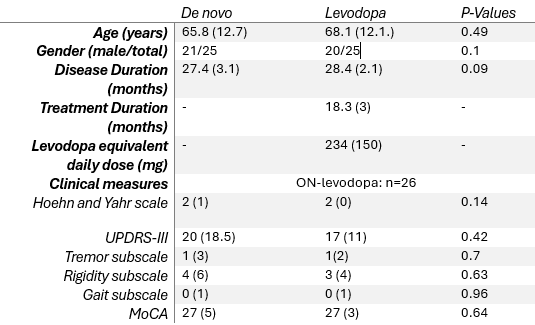

As you can see, these two groups have various factors controlled for, including their disease duration. 

Here is today's challenge question(s): 

"To what extent are regions like the cerebellum, basal ganglia, and corpus callosum differ in de novo and levodopa-medicated PD patients?"

- Since we are now looking into specific regions of interests (ROIs), we normally need to calculate their relative morphological data based on the total intracranial volume (TIV) per individual. This is to avoid subject variability.

- **For those who are still unfamiliar with the MRI data,** please use the normalised data in the file ("normMean").

- **For those who want extra challenge,** please try normalising the regions yourself using the estimated TIV (eTIV) data also present in the aseg.stats file.

- For the simplicity of this task, please just compare the volumetric data that are available.

First, let's load all the data. Subcortical data are stored in **aseg.stats** file. 

denovo_dir = 'Brain Images\cs_denovo';
ldopa_dir = 'Brain Images\cs_ldopa';

addpath("Functions\");

dn_Vol = [];
ld_vol = [];

dn_participants = dir(denovo_dir);
dn_participants = dn_participants([dn_participants.isdir] & ~ismember({dn_participants.name}, {'.', '..', '.DS_Store'})); 

ld_participants = dir(ldopa_dir);
ld_participants = ld_participants([ld_participants.isdir] & ~ismember({ld_participants.name}, {'.', '..', '.DS_Store'})); 

Since we are now loading selected ROIs per group, it is easier to make a table for comparison! I will share how to make the de novo table, and you can try making the levodopa table after. 

dn_table = table();
ld_table = table();

for i = 1:length(dn_participants)
    stats_file = fullfile(denovo_dir, dn_participants(i).name, 'aseg.stats');
    
    if exist(stats_file, 'file')
        vol_etiv_table = extract_vol_etiv(stats_file); 
        
        if isempty(vol_etiv_table)
            fprintf('The table for participant %s is empty.\n', dn_participants(i).name);
            continue;
        end

        current_row = table(); 
        current_row.ParticipantID = {dn_participants(i).name};
        
        for j = 1:height(vol_etiv_table)
            region = vol_etiv_table.Region{j}; 
            Volume_mm3 = vol_etiv_table.Volume_mm3(j); 
            
            current_row.(region) = Volume_mm3; 
        end
        
        current_row.eTIV = vol_etiv_table.eTIV(1); 
        
        dn_table = [dn_table; current_row];
    else
        fprintf('Stats file missing for participant: %s\n', dn_participants(i).name);
    end
end

Let's display the table!

dn_table

dn_table = 24×19 table
       ParticipantID       Left-Cerebellum-White-Matter    Left-Cerebellum-Cortex    Left-Thalamus    Left-Caudate    Left-Putamen    Left-Pallidum    Right-Cerebellum-White-Matter    Right-Cerebellum-Cortex    Right-Thalamus    Right-Caudate    Right-Putamen    Right-Pallidum    CC_Posterior    CC_Mid_Posterior    CC_Central    CC_Mid_Anterior    CC_Anterior       eTIV   
    ___________________    ____________________________    ______________________    _____________    ____________    ____________    _____________    

Please try creating the levdopa group table:

for i = 1:length(ld_participants)
    stats_file = fullfile(ldopa_dir, ld_participants(i).name, 'aseg.stats');
    
    if exist(stats_file, 'file')
        norm_table = extract_normalised_vols(stats_file);
        
        current_row = table(); 
        current_row.ParticipantID = {dn_participants(i).name};
        
        for j = 1:height(vol_etiv_table)
            region = vol_etiv_table.Region{j}; 
            Volume_mm3 = vol_etiv_table.Volume_mm3(j); 
            
            current_row.(region) = Volume_mm3; 
        end
        
        current_row.eTIV = vol_etiv_table.eTIV(1); 
        
        ld_table = [dn_table; current_row];
    else
        fprintf('Stats file missing for participant: %s\n', ld_participants(i).name);
    end
end

                 Region                  Normalised_Volume
    _________________________________    _________________

    {'Left-Cerebellum-White-Matter' }         81.346      
    {'Left-Cerebellum-Cortex'       }         59.424      
    {'Left-Thalamus'                }          82.81      
    {'Left-Caudate'                 }         74.082      
    {'Left-Putamen'                 }         80.192      
    {'Left-Pallidum'                }         95.625      
    {'Right-Cerebellum-White-Matter'}          81.15      
    {'Right-Cerebellum-Cortex'      }         60.896      
    {'Right-Thalamus'               }         83.198      
    {'Right-Caudate'                }         76.155      
    {'Right-Putamen'                }         82.198      
    {'Right-Pallidum'               }         98.042      
    {'CC_Posterior'                 }         98.404      
    {'CC_Mid_Posterior'             }         

ld_table

ld_table = 25×19 table
       ParticipantID       Left-Cerebellum-White-Matter    Left-Cerebellum-Cortex    Left-Thalamus    Left-Caudate    Left-Putamen    Left-Pallidum    Right-Cerebellum-White-Matter    Right-Cerebellum-Cortex    Right-Thalamus    Right-Caudate    Right-Putamen    Right-Pallidum    CC_Posterior    CC_Mid_Posterior    CC_Central    CC_Mid_Anterior    CC_Anterior       eTIV   
    ___________________    ____________________________    ______________________    _____________    ____________    ____________    _____________    

Nice! Since we have regional data, let's see how to normalise them.

To normalise, we simply need to divide each region to the eTIV value. I'll share an example with the de novo group, and you can try it with the levdopa group. 

dn_varNames = dn_table.Properties.VariableNames;
data_columns = 2:18;  
etiv_column = 19;

dn_data = dn_table{:, data_columns}; 
dn_eTIV = dn_table{:, etiv_column};

normalised_dn_data = dn_data ./ dn_eTIV;
normalised_dn_table = dn_table;

normalised_dn_table{:, data_columns} = normalised_dn_data;

normalised_dn_table(:, etiv_column) = []; % Since now we no longer need the eTIV column

normalised_dn_table

normalised_dn_table = 24×18 table
       ParticipantID       Left-Cerebellum-White-Matter    Left-Cerebellum-Cortex    Left-Thalamus    Left-Caudate    Left-Putamen    Left-Pallidum    Right-Cerebellum-White-Matter    Right-Cerebellum-Cortex    Right-Thalamus    Right-Caudate    Right-Putamen    Right-Pallidum    CC_Posterior    CC_Mid_Posterior    CC_Central    CC_Mid_Anterior    CC_Anterior
    ___________________    ____________________________    ______________________    _____________    ____________    ____________    _____________    ____________________

% Write your code for ld_table normalisation here

Now, as an example, I will guide you through comparing cerebellum between de novo and levodopa groups. First we will identify which columns belong to the cerebellum: 

cerebellum_columns = {'Left-Cerebellum-White-Matter', 'Left-Cerebellum-Cortex', 'Right-Cerebellum-White-Matter', 'Right-Cerebellum-Cortex'};

Now let's specify from the de novo and levodopa tables: 

dn_cerebellum = normalised_dn_table(:, cerebellum_columns);
ld_cerebellum = normalised_ld_table(:, cerebellum_columns);

Let's view one? 

dn_cerebellum
ld_cerebellum

Cool! Let's now test their normality and equal variance to see if we can use parametric or non-parametric testing. 

We need to first transform the dn_cerebellum to array to test the numerical values only.

addpath("Functions\")
dn_cerebellum_array = table2array(dn_cerebellum);

h = zeros(1, size(dn_cerebellum_array, 2));
p_val = zeros(1, size(dn_cerebellum_array, 2));

for i = 1:size(dn_cerebellum_array, 2)
    [h(i), p_val(i)] = swtest(dn_cerebellum_array(:, i));
end

h

We know the hypothesis testing has 1's, meaning our data are not normally distributed. Thus, we can skip the rest and continue with non-parametric testing. 

One of the most well-known non-parametric testing we can use here is **Wilcoxon Rank-sum testing**.

For comparison, let's first convert the tables into array so we can apply testing: 

dn_cerebellum_array = table2array(dn_cerebellum);
ld_cerebellum_array = table2array(ld_cerebellum);

p_values = zeros(1, 4);
h_values = zeros(1, 4);

for i = 1:4
    dn_region_data = dn_cerebellum_array(:, i);
    ld_region_data = ld_cerebellum_array(:, i);
    
    [p_values(i), h_values(i)] = ranksum(dn_region_data, ld_region_data);
end

p_values
h_values

Interesting. Now we know the two groups at the same disease duration do not differ in the cerebllar volume. What about the other two regions (basal ganglia and corpus callosum)? 

% Write your code here